# Quantitative Models for Data Science

# Group 9 project

## Group Members

- Matteo Spadaccia (277141)

- Valerio Romano Cadura (264851)

- Dan Mark Tolod (276181)

- Filippo Castello (not available)

## **Abalone Dataset analysis**

We consider measurements of a sample of abalones.The age of an abalone is determined by cutting the shell through the cone, staining it, and counting the number of rings (*R*) through a microscope, which is a boring and time-consuming task. Other measurements (we will suppose to have data about *L*ength, *D*epth, *H*eight and *W*eight), which are easier to obtain, are used to predict the age.

### **Task 1**

Firstly we want to analyze how much single-regressor linear models can approximate the response variable.

#### **Task 1.1 - dataset importing and variables setting**

We start by importing the data:

% Data importing
abalone_data = readtable('Abalone_data.xlsx')

abalone_data = 100×5 table
      L        D        H        W       R 
    _____    _____    _____    ______    __

     0.52      0.4     0.12     0.823    15
    0.465     0.36     0.11    0.4955     7
     0.66     0.53    0.185    1.3485    12
    0.585    0.465     0.19     1.171    17
      0.3     0.23     0.08    0.1275     8
    0.375     0.28     0.08     0.226     6
    0.575     0.47    0.165     0.853    16
     0.48     0.37    0.135    0.6315     7
    0.605     0.49     0.15    1.1345     9
    0.575    0.475     0.16     0.895     9
     0.63     0.49    0.225     1.336    10
     0.32    0.235    0.065    0.1385     5
     0.39     0.29     0.09    0.2625     7
    0.515     0.35    0.155    0.9225     9
    0.585    0.475    0.165     1.053    11
    0.605     0.49     0.14    0.9755    10


Then we save them as a table in a .mat file:

% Data saving 
save('Abalone_data.mat','abalone_data')

As asked by this task, we store the vectors of observations of the response variable and of each regressor in separate variables:

% Storing of each regressors' and response variable's arrays
L = table2array(abalone_data(:,1));
D = table2array(abalone_data(:,2));
H = table2array(abalone_data(:,3));
W = table2array(abalone_data(:,4));
R = table2array(abalone_data(:,5));

Moreover, we decided to split our dataset into training and testing samples, using approximately the $10%$% of it to test a model we will implement. We want to separate the the training and the testing data randomly in order to avoid biasing the data, but we implemented a random seed in order to make it possible to obtain always the same results (comment it if it is needed to obtain a new model each time the script is run).

Here is the related code:

% Random seed definition to obtain always the same permutations and results
rng('default')
s = rng;
% (comment if needed)

% Obtaining datasets sizes
[m,n] = size(abalone_data);

% Defining partitions' sizes
partition = 0.90;

% Dividing the dataset into a train-part and a test-part
positions = randperm(m); % returns a row vector containing a random permutation of the integers from 1 to m
Data_train = abalone_data(positions(1:round(partition*m)),:);
Data_test = abalone_data(positions(round(partition*m)+1:end),:);

% Preparing the variables and separating data into individual regressors and response variable arrays
X_train = Data_train(:,1:4);
X_test = Data_test(:,1:4);
y_train = Data_train(:,5);
y_test = Data_test(:,5);
LDHW_train = table2array(X_train);
LDHW_test = table2array(X_test);
L_train = table2array(X_train(:,1));
L_test = table2array(X_test(:,1));
D_train = table2array(X_train(:,2));
D_test = table2array(X_test(:,2));
H_train = table2array(X_train(:,3));
H_test = table2array(X_test(:,3));
W_train = table2array(X_train(:,4));
W_test = table2array(X_test(:,4));
R_train = table2array(y_train);
R_test = table2array(y_test);
m_train = length(R_train);
m_test = length(R_test);
regressors = ['Length';'Depth ';'Height';'Weight'];

#### **Task 1.2 - response variable vs. regressors scatterplots generation**

Now that we have our train and test sets, we want to plot the train data in order to visualize the behaviour of each input variable, therefore we will generate four distinct scatterplots of the response variable vs. each of the regressors:

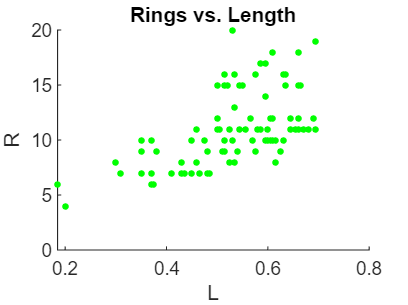

% Plotting the response variable vs each of the regressors
hold off
scatter(L_train,R_train,10,'filled','green')
ylabel('R')
xlabel('L')
title('Rings vs. Length')

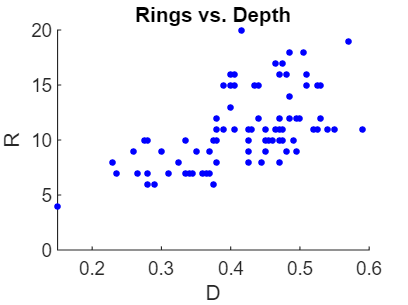

scatter(D_train,R_train,10,'filled','blue')
ylabel('R')
xlabel('D')
title('Rings vs. Depth')

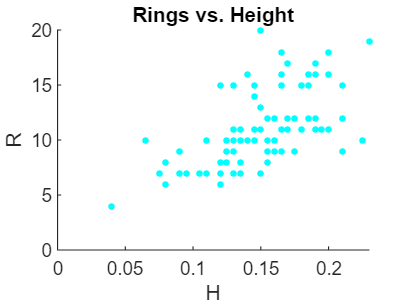

scatter(H_train, R_train,10,'filled','cyan')
ylabel('R')
xlabel('H')
title('Rings vs. Height')

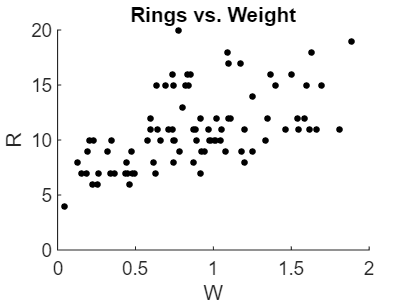

scatter(W_train, R_train,10,'filled','black')
ylabel('R')
xlabel('W')
title('Rings vs. Weight')

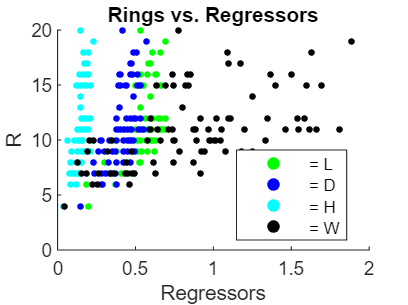


% Plotting the response variable vs each of the regressors (single graph)
scatter(L_train, R_train,10,'filled','green')
hold on
scatter(D_train, R_train,10,'filled','blue')
scatter(H_train, R_train,10,'filled','cyan')
scatter(W_train, R_train,10,'filled','black')
ylabel('R')
xlabel('Regressors')
title('Rings vs. Regressors')
legend('= L','= D', '= H', '= W','location','best')
hold off

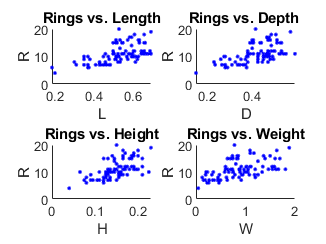


% Plotting the response variable vs each of the regressors (single figure)
figure()
for i = 1:4
    subplot(2,2,i)
    scatter(LDHW_train(:,i),R_train,'b.')
    title(['Rings vs. ' regressors(i,1:6)])
    xlabel(regressors(i,1))
    ylabel('R')
end

figure()

#### **Task 1.3 - response-regressors linear relationship plausibility comment**

Observing the scatterplots, we can confirm that, as it was possible to hypothesize a priori, the age of the abalone and therefore the number of its *R*ings is more or less proportional to its *W*eight, therefore basically to its volume. Concerning the other regressors, we have an indirect corrispondence due to the volume-age one. However, not for these reasons the *R*ings-*W*eight porportionality shall be the most linear.

#### Task 1.4 - single-regressor linear models building

We now proceed by 'manually' applying the least-squares method to each pair response variable-regressor:

% Applying the LSM to the pair R-L
X_L = [ones(m_train,1), L_train];
XtX_L = X_L' * X_L;
XtX_inv_L = inv(XtX_L);
Xty_L = X_L' * R_train;
beta_hat_L = XtX_inv_L * Xty_L;
beta_0_L = beta_hat_L(1);
beta_1_L = beta_hat_L(2);
l_reg_L = @(x) beta_0_L + beta_1_L * x;

% Applying the LSM to the pair R-D
X_D = [ones(m_train,1), D_train];
XtX_D = X_D' * X_D;
XtX_inv_D = inv(XtX_D);
Xty_D = X_D' * R_train;
beta_hat_D = XtX_inv_D * Xty_D;
beta_0_D = beta_hat_D(1);
beta_1_D = beta_hat_D(2);
l_reg_D = @(x) beta_0_D + beta_1_D * x;

% Applying the LSM to the pair R-H
X_H = [ones(m_train,1), H_train];
XtX_H = X_H' * X_H;
XtX_inv_H = inv(XtX_H);
Xty_H = X_H' * R_train;
beta_hat_H = XtX_inv_H * Xty_H;
beta_0_H = beta_hat_H(1);
beta_1_H = beta_hat_H(2);
l_reg_H = @(x) beta_0_H + beta_1_H * x;

% Applying the LSM to the pair R-W
X_W = [ones(m_train,1), W_train];
XtX_W = X_W' * X_W;
XtX_inv_W = inv(XtX_W);
Xty_W = X_W' * R_train;
beta_hat_W = XtX_inv_W * Xty_W;
beta_0_W = beta_hat_W(1);
beta_1_W = beta_hat_W(2);
l_reg_W = @(x) beta_0_W + beta_1_W * x;

#### Task 1.5 - single-regressor linear models plotting

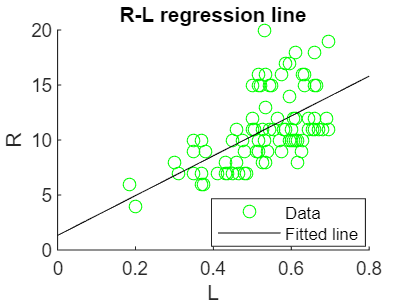

% Plotting the regression line of the pair R-L
scatter(L_train,R_train,'green')
hold on
fplot(l_reg_L, [0 0.8],'black')
ylabel('R')
xlabel('L')
title('R-L regression line')
legend('Data','Fitted line','Location','best')
hold off

beta_0_L

beta_0_L = 1.3262

beta_1_L

beta_1_L = 18.1002

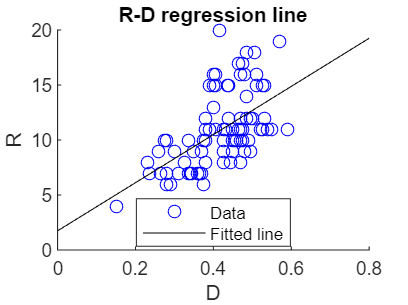


% Plotting the regression line of the pair R-D
scatter(D_train,R_train,'blue')
hold on
fplot(l_reg_D, [0 0.8],'black')
ylabel('R')
xlabel('D')
title('R-D regression line')
legend('Data','Fitted line','Location','best')
hold off

beta_0_D

beta_0_D = 1.7416

beta_1_D

beta_1_D = 21.8880

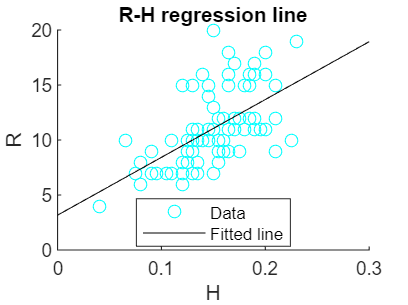


% Plotting the regression line of the pair R-H
scatter(H_train,R_train,'cyan')
hold on
fplot(l_reg_H, [0 0.3],'black')
ylabel('R')
xlabel('H')
title('R-H regression line')
legend('Data','Fitted line','Location','best')
hold off

beta_0_H

beta_0_H = 3.1692

beta_1_H

beta_1_H = 52.5592

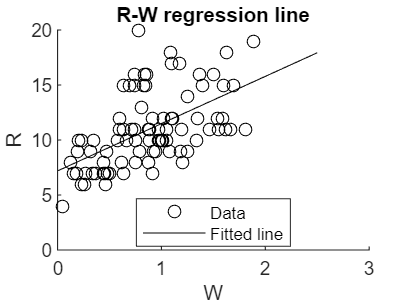


% Plotting the regression line of the pair R-W
scatter(W_train,R_train,'black')
hold on
fplot(l_reg_W, [0 2.5],'black')
ylabel('R')
xlabel('W')
title('R-W regression line')
legend('Data','Fitted line','Location','best')
hold off

beta_0_W

beta_0_W = 7.1921

beta_1_W

beta_1_W = 4.2962

#### Task 1.6 - obtained coefficeints comment

In this case, $\beta_{0}$ is the constant y-intercept of the line generated by each model (virtually the age at which the selected regressor equals 0) and $\beta_{1}$ is its angular coefficient in each case (the inverse of the estimated 'speed' at which the selected regressor value increases while the abalone becomes older).

Therefore, exclusively basing on the model we obtained, it is possible to assert that an abalone probably grows in dimension mainly by increasing its *W*eight and slightly changing its *H*eight, however that was easily conceivable as that are the highest and least valued measures, probably the proportions of the animal are quite constant during its time.

#### Task 1.7 - RMSEs computation and comparison

In order to compare the model obtained, we 'manually' compute the Root Mean Square Error of each one:

% Computing the RMSE of the pair R-L
y_hat_L = X_L * beta_hat_L;
epsilon_hat_L = R_train - y_hat_L;
epsilon_hat_squared_L = epsilon_hat_L .^2;
RMSE_L_train = sqrt(mean(epsilon_hat_squared_L))

RMSE_L_train = 2.7158


% Computing the RMSE of the pair R-D
y_hat_D = X_D * beta_hat_D;
epsilon_hat_D = R_train - y_hat_D;
epsilon_hat_squared_D = epsilon_hat_D .^2;
RMSE_D_train = sqrt(mean(epsilon_hat_squared_D))

RMSE_D_train = 2.7604


% Computing the RMSE of the pair R-H
y_hat_H = X_H * beta_hat_H;
epsilon_hat_H = R_train - y_hat_H;
epsilon_hat_squared_H = epsilon_hat_H .^2;
RMSE_H_train = sqrt(mean(epsilon_hat_squared_H))

RMSE_H_train = 2.6924


% Computing the RMSE of the pair R-W
y_hat_W = X_W * beta_hat_W;
epsilon_hat_W = R_train - y_hat_W;
epsilon_hat_squared_W = epsilon_hat_W .^2;
RMSE_W_train = sqrt(mean(epsilon_hat_squared_W))

RMSE_W_train = 2.7815

We can see that the Root Mean Square Errors are comparable within the regressors, even if *H* has a slightly lower value, so we can assume it to have the most linear proportionality among the regressors.

#### Task 1.8 - reliabilty of predicting over new observations

We now try to make some predictions with the test sample extracted from the dataset and estimate their accuracy by their Root Mean Square Errors:

% Computing the test RMSE of the pair R-L
y_pred_L = l_reg_L(L_test);
SSR_L = sum((y_pred_L - R_test) .^2);
MSE_L = SSR_L / m_test;
RMSE_L_test = sqrt(MSE_L)

RMSE_L_test = 3.0273


% Computing the test RMSE of the pair R-D
y_pred_D = l_reg_D(D_test);
SSR_D = sum((y_pred_D - R_test) .^2);
MSE_D = SSR_D / m_test;
RMSE_D_test = sqrt(MSE_D)

RMSE_D_test = 3.0953


% Computing the test RMSE of the pair R-H
y_pred_H = l_reg_H(H_test);
SSR_H = sum((y_pred_H - R_test) .^2);
MSE_H = SSR_H / m_test;
RMSE_H_test = sqrt(MSE_H)

RMSE_H_test = 2.9726


% Computing the test RMSE of the pair R-W
y_pred_W = l_reg_W(W_test);
SSR_W = sum((y_pred_W - R_test) .^2);
MSE_W = SSR_W / m_test;
RMSE_W_test = sqrt(MSE_W)

RMSE_W_test = 3.0735

We can confirm that generally all the predictor variables are comparably good linear regressors, moreover *H* is again the most valid one.

### **Task 2**

Also considering our previous analysis' results, we can state that a multivariate regression could be a good idea with this dataset. For this reason, we want to check whether using multiple regressor for the prediction decrease the Root Mean Squared Error.

#### **Task 2.1 - all predictor variables model computation**

Firstly, we consider the linear model with all the predictor variables, trying to determine the best linear model that fits the data, among those who satisfy:

$R_i = \beta_0 + \beta_1 L_i + \beta_2 D_i + \beta_3 H_i + \beta_4 W_i + \varepsilon_i$ *,   *$i = 1, \dots,90$;

with *m *= 100 as the number of observations of which 90% are part of the train-set, whereas $L_i, D_i, H_i, W_i, R_i$  as refernce to the *L*ength, *Depth*, *H*eight and *W*eight of the abalone.

We introduce:

$\mathbf y = \left[\matrix{R_1 \cr \vdots \cr R_{90}}\right]$ (response variable's vector);

$X= \left[\matrix{1 & L_1 & D_1 & H_1 & W_1 \cr \vdots & \vdots &\vdots & \vdots & \vdots \cr 1 & L_{90} & D_{90} & H_{90} & W_{90}}\right]$ (design matrix);

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1 \cr \beta_2 \cr \beta_3 \cr \beta_4}\right]$ (coefficients' vector);

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_{90}}\right]$ (residuals' vector).

We need to minimize the residual sum of squares $||\mathbf \varepsilon||^2 = ||\mathbf y - X \mathbf \beta||^2$, finding the $\mathbf \beta$ that minimizes the distance between $\mathbf y$ and $X\mathbf \beta$. Equivalently we have to face the linear system $\mathbf y = X\mathbf \beta$ in the least-squares sense, solving the normal equation $X^TX \mathbf \beta = X^T \mathbf y$.

We know that if $X$ has linearly independent columns (if $X^TX$ is invertible), then the best linear model fitting the data has coefficients $\hat \mathbf \beta = (X^TX)^{-1}X^T\mathbf y$.

Therefore, we proceed with the multivariate regression:

% Computing the multivariate linear regression with all the regressors
X_all = [ones(m_train,1) LDHW_train];
beta_hat_all = X_all \ R_train; % \ solves the linear system if possible if not possible it solves it in l-s-sense
beta_0_all = beta_hat_all(1)

beta_0_all = 0.4787

beta_1L_all = beta_hat_all(2)

beta_1L_all = 11.0449

beta_2D_all = beta_hat_all(3)

beta_2D_all = -0.0359

beta_3H_all = beta_hat_all(4)

beta_3H_all = 38.7528

beta_4W_all = beta_hat_all(5)

beta_4W_all = -1.2830


% Computing the RMSE of the all-regressors multivariate regression
y_hat_all = X_all * beta_hat_all;
epsilon_hat_all = R_train - y_hat_all;
epsilon_hat_squared_all = epsilon_hat_all .^2;
RMSE_all = sqrt(mean(epsilon_hat_squared_all))

RMSE_all = 2.6443


% Computing the test RMSE of the all-regressors multivariate regression
y_pred_all = beta_0_all + beta_1L_all * L_test + beta_2D_all * D_test + beta_3H_all * H_test + beta_4W_all * W_test;
SSR_all = sum((y_pred_all - R_test) .^2);
MSE_all = SSR_all / m_test;
RMSE_all_test = sqrt(MSE_all)

RMSE_all_test = 2.9819

#### Task 2.2 - all predictor variables model comment

In this case, $\beta_{0}$ is the constant y-intercept of the hyperplane generated by the model (virtually the age at which all the regressors equal 0), while $\beta_{1}$, $\beta_{2}$, $\beta_{3}$ and $\beta_{4}$ are the angular coefficients of the line generated by the interception of the hyperplane respectively with the plane *R*-*L*, *R*-*D*, *R*-*H* and *R*-*W *(the inverse of the estimated 'speed' at which the related regressor value increases while the abalone becomes older, considering the other regressors constantly equal to 0).

We can easily observe that the result of the latter model on the train-set is slightly better than the one obtained with the single-predictor regressions, while the prediction on the test-set is of equivalent quality compared to the one based on the regression over *H*. In any case, there is no significant improvement.

#### Task 2.3 - all two-/three-regressors linear models computation and comment

Searching for a more accurate model, we may try to use just some of the regressors and verify if the result present better quality considering the Root Mean Square Errors. Therefore, we proceed by computing all the two-/three-regressors linear models:

% Computing all the regressors couples' linear regressions
two_reg_data = Dictionary;
for i = 1:4
    for j = i+1:4
        % Computing the multivariate linear regression with the two selected regressors
        X_temp = [ones(m_train,1) LDHW_train(:,[i j])];
        beta_hat_temp = X_temp \ R_train; % \ solves the linear system if possible if not possible it solves it in l-s-sense
        beta_0_temp = beta_hat_temp(1);
        beta_1_temp = beta_hat_temp(2);
        beta_2_temp = beta_hat_temp(3);

        % Computing the RMSE of the multivariate regression with the two selected regressors
        y_hat_temp = X_temp * beta_hat_temp;
        epsilon_hat_temp = R_train - y_hat_temp;
        epsilon_hat_squared_temp = epsilon_hat_temp .^2;
        RMSE_temp = sqrt(mean(epsilon_hat_squared_temp));

        % Computing the test RMSE of the multivariate regression with the two selected regressors
        y_pred_temp = beta_0_temp + beta_1_temp * LDHW_test(:,i) + beta_2_temp * LDHW_test(:,j);
        SSR_temp = sum((y_pred_temp - R_test) .^2);
        MSE_temp = SSR_temp / m_test;
        RMSE_temp_test = sqrt(MSE_temp);

        % Storing data in a dictionary
        two_reg_data(strcat(regressors(i,1:6),'-',regressors(j,1:6))) = [RMSE_temp;RMSE_temp_test;beta_hat_temp];
    end
end

% Computing all the regressors triplets' linear regressions
three_reg_data = Dictionary;
for i = 1:4
    % Computing the multivariate linear regression with the three selected regressors
    X_temp = [ones(m_train,1) LDHW_train(:,cat(2,1:(i-1),(i+1):4))];
    beta_hat_temp = X_temp \ R_train; % \ solves the linear system if possible if not possible it solves it in l-s-sense
    beta_0_temp = beta_hat_temp(1);
    beta_1_temp = beta_hat_temp(2);
    beta_2_temp = beta_hat_temp(3);
    beta_3_temp = beta_hat_temp(4);

    % Computing the RMSE of the multivariate regression with the three selected regressors
    y_hat_temp = X_temp * beta_hat_temp;
    epsilon_hat_temp = R_train - y_hat_temp;
    epsilon_hat_squared_temp = epsilon_hat_temp .^2;
    RMSE_temp = sqrt(mean(epsilon_hat_squared_temp));

    % Computing the test RMSE of the multivariate regression with the three selected regressors
    y_pred_temp = (beta_0_temp + beta_hat_temp(2:4)' * LDHW_test(:,cat(2,1:(i-1),(i+1):4))')';
    SSR_temp = sum((y_pred_temp - R_test) .^2);
    MSE_temp = SSR_temp / m_test;
    RMSE_temp_test = sqrt(MSE_temp);

    % Storing data in a dictionary
    three_reg_data(strcat('allBut',regressors(i,1:6))) = [RMSE_temp;RMSE_temp_test;beta_hat_temp];
end

% Displaying results of all the regressors couples' linear regressions
reg_couples_temp = two_reg_data.Keys;
for i = 1:length(two_reg_data.Keys)
    two_reg_data_sel_temp = two_reg_data(char(reg_couples_temp(i)));
    disp(strcat('RMSE_',char(reg_couples_temp(i)),'_train: ',num2str(two_reg_data_sel_temp(1))))
end

RMSE_Length-Depth_train:2.7113
RMSE_Length-Height_train:2.6509
RMSE_Length-Weight_train:2.7074
RMSE_Depth-Height_train:2.6744
RMSE_Depth-Weight_train:2.744
RMSE_Height-Weight_train:2.6901



% Displaying results of all the regressors triplets' linear regressions
reg_couples_temp = three_reg_data.Keys;
for i = 1:length(three_reg_data.Keys)
    three_reg_data_sel_temp = three_reg_data(char(reg_couples_temp(i)));
    disp(strcat('RMSE_',char(reg_couples_temp(i)),'_train: ',num2str(three_reg_data_sel_temp(1))))
end

RMSE_allButLength_train:2.6724
RMSE_allButDepth_train:2.6443
RMSE_allButHeight_train:2.7067
RMSE_allButWeight_train:2.65


Observing the results, we can conclude that the best linear models among the ones just created is the one considering all the regressors but the *D*epth, equally valuable than the one considering all the regressors simultaneously (this was easily conceivable as its $\beta_{2}$, related to the *D*epth value, was similar to 0) . For this reason, we may appreciate to verify its performance over the test-set, considering the related Root Mean Square Error:

% displaying the test RMSE of the model considering all the regressors but Depth
allButDepth_reg_data = three_reg_data('allButDepth');
disp(strcat('RMSE_allButDepth_test: ',num2str(allButDepth_reg_data(2))))

RMSE_allButDepth_test:2.982


#### Task 2.4 - best partial model's coefficients presentation

Moreover, we may like to express the coefficients of the linear model considering all the regressors but the *D*epth:

% displaying the coefficients of the model considering all the regressors but Depth
beta_0_allButDepth = allButDepth_reg_data(3)

beta_0_allButDepth = 0.4753

beta_1L_allButDepth = allButDepth_reg_data(4)

beta_1L_allButDepth = 11.0286

beta_2H_allButDepth = allButDepth_reg_data(5)

beta_2H_allButDepth = 38.7464

beta_3W_allButDepth = allButDepth_reg_data(6)

beta_3W_allButDepth = -1.2854

#### Task 2.5 - possible non linear proportionality consideration

By all the previous analysis, also because the performance of the model not considering *D*epth over the test-data is slightly worse than that one of the model considering all the regressors, we can assert that the best linear model for the *R*ing number prediction over this dataset is the one taking into account all the predictor variables.

Even if in general the linear models performed reasonably well, we may also use alternative models to suit the data. Indeed, we will use a polynomial equation to determine which non-linear model best fits each of the response variable-regressor pair. 

This can be achieved by transforming data, applying suitable functions to the observations in the response and in the predictor variable. In this way, we can write a general linear model as $g(y_i) = \beta_0 + \beta_1 f_1(x_i) + \beta_2 f_2(x_i) + \cdots \beta_n f_n(x_i) + \epsilon_i, \, i = 1, \dots, 90$. The functions $f_1, \dots, f_n, g$ determine the shape of the fitting curve.

The model above can be written as $\mathbf y = X\mathbf \beta + \mathbf \epsilon$, with:

$\mathbf y = \left[\matrix{g(y_1) \cr \vdots \cr g(y_{90})}\right]$ (the vector of the response variable);

$X= \left[\matrix{1 & f_1(x_1) & f_2(x_1) & \cdots & f_n(x_1) \cr \vdots & \vdots &\vdots & \ddots & \vdots \cr 1 & f_1(x_{90}) & f_2(x_{90}) & \cdots & f_n(x_{90})}\right]$ (the design matrix);

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1 \cr \beta_2 \cr \vdots \cr \beta_{m}}\right]$ (the vector of coefficients);

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_{90}}\right]$ (the vector of residuals).

Therefore, we can determine the best coefficients for these general models solving the normal equation: $X^TX \mathbf \beta = X^T \mathbf y$.

#### Task 2.6,7 - best polynomial models' coefficients computation and plots

We can find the right polynomial by looping using different polynomial equation and check for the one that yields the smaller errors. We would like to plot the obtained curve and to apply it upon the test-set and analyze the results too. Here we try with polynomials of degree $\le 5$:

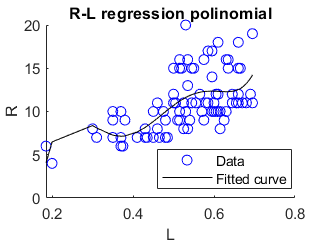

Degree:5  RMSE:2.6431  RMSE_test:3.2631


Beta_hat:-226.53677       3078.1744     -15312.1183      36187.3894     -40803.6735      17695.7623


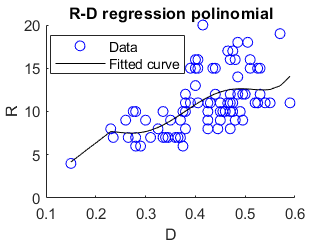

Degree:5  RMSE:2.7064  RMSE_test:3.3295


Beta_hat:-118.469016      1995.75238     -12115.0435      35070.2025     -48257.4909      25417.2768


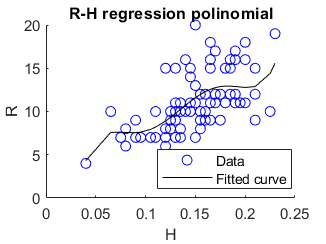

Degree:5  RMSE:2.629  RMSE_test:3.313


Beta_hat:-37.087687698      2132.1612872     -38538.237161      326180.53757     -1280875.4921      1890389.4954


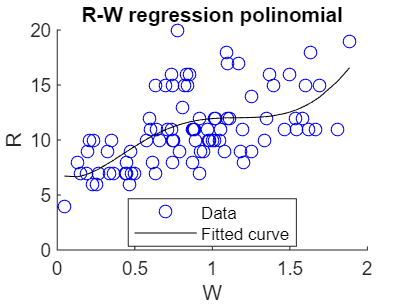

Degree:5  RMSE:2.6885  RMSE_test:3.0398


Beta_hat:6.98405     -7.88251      49.0419     -60.0373      28.1997     -4.35853


% Computing all the polinomial models for the various regressors and choosing the best one for each by RMSE
DegRMSEs_poly = zeros(1,8);
for i=1:4
    RMSEs_temp = zeros(1,5);
    Xiy = [X_train(:,i) y_train];
    sorted_Xiy = sortrows(Xiy,1);
    X_train_i = table2array(sorted_Xiy(:,1));
    y_train_i = table2array(sorted_Xiy(:,2));
    for j=1:5
        if j == 1 
            poly_temp = [ones(m_train,1) X_train_i];
        elseif j == 2
            poly_temp = [ones(m_train,1) X_train_i X_train_i.^2];
        elseif j == 3
            poly_temp = [ones(m_train,1) X_train_i X_train_i.^2 X_train_i.^3];
        elseif j == 4
            poly_temp = [ones(m_train,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4];
        elseif j == 5
            poly_temp = [ones(m_train,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4 X_train_i.^5];
        end
        beta_hat_temp = poly_temp \ y_train_i;
        y_hat_temp = poly_temp * beta_hat_temp;
        epsilon_hat_temp = y_train_i - y_hat_temp;
        SSR_temp = sum(epsilon_hat_temp .^2);
        RMSE_temp = sqrt(SSR_temp / m_train);
        RMSEs_temp(j) = RMSE_temp;    
    end

    % Considering the best polinomial model for each regressor by RMSEs
    [bestRMSE_temp, bestRMSE_idx_temp] = min(RMSEs_temp);
    DegRMSEs_poly(i*2-1) = bestRMSE_idx_temp;
    DegRMSEs_poly(i*2) = bestRMSE_temp;

    % Displaying the best polinomial model for each regressor
    if bestRMSE_idx_temp == 1 
        poly_temp = [ones(m_train,1) X_train_i];
    elseif bestRMSE_idx_temp == 2
        poly_temp = [ones(m_train,1) X_train_i X_train_i.^2];
    elseif bestRMSE_idx_temp == 3
        poly_temp = [ones(m_train,1) X_train_i X_train_i.^2 X_train_i.^3];
    elseif bestRMSE_idx_temp == 4
        poly_temp = [ones(m_train,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4];
    elseif bestRMSE_idx_temp == 5
        poly_temp = [ones(m_train,1) X_train_i X_train_i.^2 X_train_i.^3 X_train_i.^4 X_train_i.^5];
    end
    beta_hat_temp = poly_temp \ y_train_i;
    y_hat_temp = poly_temp * beta_hat_temp;
    figure()
    scatter(X_train_i,y_train_i,'b')
    title(strcat('R-',regressors(i),' regression polinomial'))
    xlabel(regressors(i,1))
    ylabel('R')
    hold on
    plot(X_train_i,y_hat_temp,'black')
    legend('Data','Fitted curve','Location','best')
    hold off
    
    % Computing the best polinomial model's test RMSE
    if bestRMSE_idx_temp == 1 
        poly_test_temp = [ones(m_test,1) LDHW_test(:,i)];
    elseif bestRMSE_idx_temp == 2
        poly_test_temp = [ones(m_test,1) LDHW_test(:,i) LDHW_test(:,i).^2];
    elseif bestRMSE_idx_temp == 3
        poly_test_temp = [ones(m_test,1) LDHW_test(:,i) LDHW_test(:,i).^2 LDHW_test(:,i).^3];
    elseif bestRMSE_idx_temp == 4
        poly_test_temp = [ones(m_test,1) LDHW_test(:,i) LDHW_test(:,i).^2 LDHW_test(:,i).^3 LDHW_test(:,i).^4];
    elseif bestRMSE_idx_temp == 5
        poly_test_temp = [ones(m_test,1) LDHW_test(:,i) LDHW_test(:,i).^2 LDHW_test(:,i).^3 LDHW_test(:,i).^4 LDHW_test(:,i).^5];
    end
    y_hat_test_temp = poly_test_temp * beta_hat_temp;
    epsilon_hat_test_temp = R_test - y_hat_test_temp;
    SSR_test_temp = sum(epsilon_hat_test_temp .^2);
    RMSE_test_temp = sqrt(SSR_test_temp / m_test);

    % Displaying information
    disp(strcat('Degree: ',num2str(DegRMSEs_poly(i*2-1)),'  RMSE: ',num2str(DegRMSEs_poly(i*2)),'  RMSE_test: ',num2str(RMSE_test_temp)))
    disp(strcat('Beta_hat: ',num2str(beta_hat_temp')))
end

#### Task 2.8 - best polynomial models' coefficients comment

As easily predictable, considering their Root Mean Square Error, the best model for each of the single-regressor polinomial case is the one with the highest degree (equal to 5 as we did not compute for higher degree models).

#### Task 2.9 - best polynomial models' RMSE analysis

Beside observing the Root Mean Square Errors of the polynomial models when applyied to the train-set and, therefore, asserting that the best single-regressor model is still the *H*eigth one; we have to consider how bad these models perform when applyed on the test set. For this reason, we can affirm that, among the linear and the 5th degree polinomial models the best is still the linear one considering all the regressors. Despite this, we have no practical information about the eventual performance quality of a 2nd, 3rd or 4th degree model, as considering their results upon the test-set would have been a different type of analysis.

#### Task 2.extra - multivariate polynomial model computation and analysis

We would rather proceed building a multivariate 2nd degree polynomial model which would 'draw' a predicting locus basing on all the regressors:

% Computing the multivariate polynomial model and its RMSE
X_multipoly = [ones(m_train,1) LDHW_train(:,1) LDHW_train(:,1).^2 LDHW_train(:,2) LDHW_train(:,2).^2 LDHW_train(:,3) LDHW_train(:,3).^2 LDHW_train(:,4) LDHW_train(:,4).^2];
beta_hat_multipoly = X_multipoly \ R_train;
y_hat_multipoly = X_multipoly * beta_hat_multipoly;
epsilon_hat_multipoly = R_train - y_hat_multipoly;
epsilon_hat_multipoly_squared = epsilon_hat_multipoly .^2;
RMSE_multipoly_train = sqrt(mean(epsilon_hat_multipoly_squared))

RMSE_multipoly_train = 2.6274

We can see that using the multivariate polynomial regression the Root Mean Square Error over the train-set is the smallest we have computed so far, hence the curves fit the dataset given properly. For this reason, we want to check that the error don't increase that much on new values, computing the Root Mean Square Error over the test-set:

% Computing the multivariate polynomial model's test RMSE
X_multipoly_test = [ones(m_test,1) LDHW_test(:,1) LDHW_test(:,1).^2 LDHW_test(:,2) LDHW_test(:,2).^2 LDHW_test(:,3) LDHW_test(:,3).^2 LDHW_test(:,4) LDHW_test(:,4).^2];
y_pred_multipoly = X_multipoly_test * beta_hat_multipoly;
epsilon_pred_multipoly = R_test - y_pred_multipoly;
epsilon_pred_multipoly_squared = epsilon_pred_multipoly.^2;
RMSE_multipoly_test = sqrt(mean(epsilon_pred_multipoly_squared))

RMSE_multipoly_test = 2.9336

We can observe that the Root Mean Square Error does not increase much, in particular it is still lower than the test one computed considering all the regressors in a linear model. For this reason, we can assert that the newly created model is probably the best one to predict the *R*ing number over this dataset, so far.

### **Task 3**

Finally, we will proceed with the Principal Component Analysis.

#### **Task 3.1 - regressors' corr. matrix eigenvalues and eigenvectors computation **

Considering the data matrix whose columns are only the four predictor variables of the dataset, we want to compute their correlation matrix, then its eigenvalues and eigenvectors and display them:

% computing the eigenvalues and eigenvectors of the correlation matrix
LDHW = table2array(abalone_data(:,1:4));
corr_mat = corrcoef(LDHW)

corr_mat =     1.0000    0.9462    0.8755    0.9114
    0.9462    1.0000    0.8870    0.9248
    0.8755    0.8870    1.0000    0.9183
    0.9114    0.9248    0.9183    1.0000


[corr_eigenvectors,corr_eigenvalues] = eig(corr_mat,'vector');

% displaying the eigenvalues and eigenvectors of the correlation matrix
for i = 1:length(corr_eigenvalues)
    display(strcat('Eigenvalue: ',num2str(corr_eigenvalues(i)),', Eigenvector:'))
    for j = 1:length(corr_eigenvectors)
        display(num2str(corr_eigenvectors(j,i)))
    end
end

Eigenvalue:0.052155, Eigenvector:


0.60563
-0.76713
-0.042333
0.20722


Eigenvalue:0.071671, Eigenvector:


0.33808
0.020645
0.46854
-0.81594


Eigenvalue:0.14433, Eigenvector:


0.51833
0.3968
-0.7319
-0.19547


Eigenvalue:3.7318, Eigenvector:


0.50025
0.50363
0.49296
0.50309


#### Task 3.2 - principal components' variance proportion and scree plot

The dataset's regressors will be used in the principal component analysis, a statistical method enabling us to condense the information content of large datasets into a more manageable number of 'summary indices' for visualization and analysis; this reduction comes with a cost: the loss of information.

Let $\lambda_1 \geq \lambda_2 \geq \lambda_3 \geq \lambda_4 > 0$ be the eigenvalues of the sample covariance matrix. Recall that the total sample variance equals $\sum_{i= 1}^4 \lambda_i$ and that the proportion of total sample variance explained by the $i_{th}$ principal component is $\lambda_i$ / $\sum_{i= 1}^4 \lambda_i$

We first sort the eigenvalues in descending order and reverse the order of the eigenvectors, then we compute the total variance as the sum of the eigenvalues and we compute the proportion of each with respect to the total variance.

We want to check the scree plot too, a chart that allow us to understand the proportion of variance explained by the $i_{th}$ principal component. On the *y_axis *we have the amount of variance preserved while on the *x_axis* we have a label for each eigenvalue.

Here is the related code:

% Computing the covariance matrix and the variance proportion of each component
covar_mat = cov(LDHW)

covar_mat =     0.0120    0.0091    0.0037    0.0436
    0.0091    0.0078    0.0030    0.0357
    0.0037    0.0030    0.0015    0.0154
    0.0436    0.0357    0.0154    0.1913


[covar_eigenvectors,covar_eigenvalues] = eig(covar_mat,'vector');
total_variance = sum(covar_eigenvalues);
sorted_covar_eigenvalues = sort(covar_eigenvalues,'descend');
var_proportion = sorted_covar_eigenvalues ./ total_variance  

var_proportion =     0.9851
    0.0116
    0.0023
    0.0010


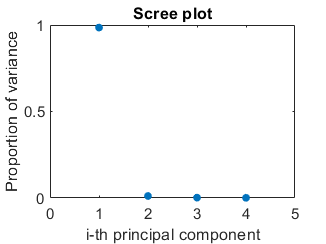


% Reverting the eigenvectors order as we sorted the eigenvalues in descending order
coeff = zeros(4,4);
for i = 1:4
    coeff(:,i) = covar_eigenvectors(:,end-i+1);
end

% Plotting the scree plot
plot(1:4,var_proportion,'.','MarkerSize',16)
xlim([0 5]);
xlabel('i-th principal component')
ylabel('Proportion of variance')
title('Scree plot')

#### Task 3.3 - cumulative proportion plot

We want to further investigate with the cumulative proportion plot, a chart which has on the *y_axis *the cumulative proportion of total sample variance explained by the $i_{th}$ component. While on the *x_axis *we have a label for each eigenvalue:      

% Plotting the cumulative proportion
cumulative_var_proportion = cumsum(var_proportion)                                

cumulative_var_proportion =     0.9851
    0.9967
    0.9990
    1.0000


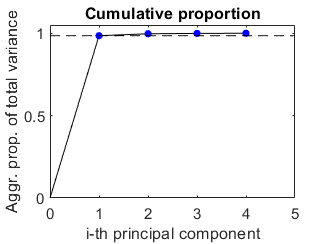

figure()
plot(0:4,[0; cumulative_var_proportion], 'k-')
hold on
plot(1:4,cumulative_var_proportion,'b.','MarkerSize',15)
xlim([0 4+1])
ylim([0 1.05])
plot(linspace(0,4+1,100),cumulative_var_proportion(1)*ones(100),'k--')
xlabel('i-th principal component')
ylabel('Aggr. prop. of total variance')
title('Cumulative proportion')

#### Task 3.4 - principal components selection

It is evident that the first component is responsible of more than $98.5%$% of the total sample variance, hence we could say that can be a useful approximation for our dataset, as including the second principal component leads to a not significant gain in variability.

#### Task 3.5 - loadings of the first two principal components comment

As we want to find the loadings of the first two sample principal components, we hace to recall that can produce the sample principal components using linear combinations of the variables in the dataset; the coefficients of these linear combinations can be called loadings and correspond to the coordinates of the eigenvectors. Below their value is displayed:

% Displaying the first two principal components' loadings
disp("1st principal component's loading:")

1st principal component's loading:


disp(num2str(coeff(:,1)'))

0.22073      0.1804     0.07709      0.9554


disp("2nd principal component's loading:")

2nd principal component's loading:


disp(num2str(coeff(:,2)'))

0.80869     0.50917     0.06192    -0.28798


Terefore, for example, the first principal component is:


$$y_1 = 0.22{x}_1 + 0.18{x}_2 + 0.08{x}_3 + 0.96{x}_4$$


While, the second one is:


$$y_2 = 0.81{x}_1 + 0.51{x}_2 + 0.06{x}_3 + 0.29{x}_4$$


Considering these results, and keeping in mind that the first principal components retains more than 98,5% of the total sample variance, we can assert that the *W*eight is generally the most influent variable on the *R*ings one.

#### Task 3.6 - principal components' scores computation

The scores are the coordinates of each of the observations in the principal components. It is useful to draw them in the plane generated by the first two eigenvectors:

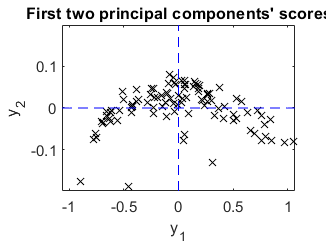

% Computing the scores by the pca function
[coeff_pca,scores_pca,latent_pca] = pca(LDHW);

% Plotting the scores in the plane generated by the first two eigenvectors
figure()
plot(scores_pca(:,1), scores_pca(:,2),'kx')
xmax = max(abs(scores_pca(:,1))) + 0.01;
ymax = max(abs(scores_pca(:,2))) + 0.01;
xlim([-xmax xmax])
ylim([-ymax ymax])
hold on
x = linspace(-xmax, xmax, m); 
y = linspace(-ymax, ymax, m);
plot(x,zeros(m),'b--')
plot(zeros(m),y,'b--')
xlabel('y_1')
ylabel('y_2')
title("First two principal components' scores")

#### Task 3.7 - principal components' scores comment

We can easily confirm that the first principal component is highly more influent than the others: the scores are 'spread' over the first eigenvector quite 10 times more than over the second one.